Load the framework (i.e. add it to MATLAB's path).

addpath( genpath([pwd filesep filesep 'imf']) )

Initialize the framework and it's global variables.

BEGIN_IMF

Create all desired generalized coordinates.

GeneralizedCoordinate q1 q2

Name and create all used coordinate systems.

CoordinateSystem I c1

Name and create all model parameters

Parameter m1 m2 l

Define, how the systems can be transformed.

This is a transformation from the I-system to the c1-System.


$$_{c1}\mathbf{v} = \mathbf{T}^{I}_{c1} \ {}_{I}\mathbf{v} \ + \ _{c1}\mathbf{r}$$


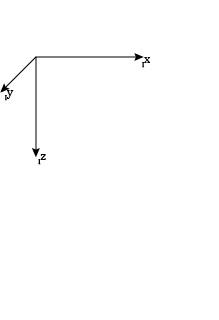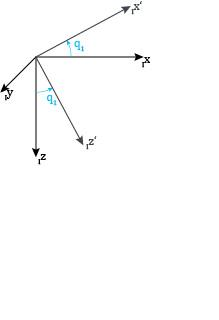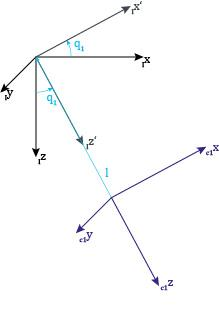

The translation describes the vector from the origin of the new system to the origin of the old system.

imf.Transformation(I, c1, imf.RotationMatrix.T2(q1), imf.Vector([0;0;-l], c1))
% imf.Transformation(I, c1, imf.RotationMatrix.T2(q1), imf.Vector([-sin(q1)*l;0;-cos(q1)*l], I))

Create a container for all bodies, forces, moments, etc.

m = imf.Model(I)

m =   Model with properties:

    inertialSystem: [1×1 imf.CoordinateSystem]
            forces: [0×0 imf.Force]
           moments: [0×0 imf.Moment]
            bodies: [0×0 imf.Body]
           gravity: [0×0 imf.Gravity]


Add gravity to the model.

g = [0 ; 0 ; 9.81];
m.gravity = imf.Gravity(g, I);

Add the first body. A point mass called 'M1' with the mass m1, located at the given position vector.

m.Add(imf.Body('M1', m1, imf.PositionVector([sin(q1)*l;0;cos(q1)*l], I)));
% m.Add(imf.Body('M1', m1, imf.PositionVector([0;0;0], c1)));

Add the first body. A point mass called 'M2' with the mass m2, located at the given position vector relativ to the c1 coordinate system.

m.Add(imf.Body('M2', m2, imf.PositionVector([sin(q2)*l,0,cos(q2)*l]', c1)));

## Compile

Use D‘Alembert‘s principle in the form of Lagrange to form the equations of motion for each body.

sdeq = m.Compile()


sdeq = 

(((-1)*cos(q2)*l*sin(q1)+(-1)*l*sin(q1)-cos(q1)*l*sin(q2))*(-(dot(q1))^2*cos(q1)*cos(q2)*l-(dot(q1))^2*cos(q1)*l+(dot(q1))^2*l*sin(q1)*sin(q2)-(dot(q2))^2*cos(q1)*cos(q2)*l+(dot(q2))^2*l*sin(q1)*sin(q2)-2*cos(q1)*cos(q2)*dot(q1)*dot(q2)*l+2*dot(q1)*dot(q2)*l*sin(q1)*sin(q2)-cos(q1)*ddot(q1)*l*sin(q2)-cos(q1)*ddot(q2)*l*sin(q2)-cos(q2)*ddot(q1)*l*sin(q1)-cos(q2)*ddot(q2)*l*sin(q1)-ddot(q1)*l*sin(q1))*m2-((-1)*cos(q2)*l*sin(q1)+(-1)*l*sin(q1)-cos(q1)*l*sin(q2))*9.81*m2+((-1)*l*sin(q1)*sin(q2)+cos(q1)*cos(q2)*l+cos(q1)*l)*(-(dot(q1))^2*cos(q1)*l*sin(q2)-(dot(q1))^2*cos(q2)*l*sin(q1)-(dot(q1))^2*l*sin(q1)-(dot(q2))^2*cos(q1)*l*sin(q2)-(dot(q2))^2*cos(q2)*l*sin(q1)-2*cos(q1)*dot(q1)*dot(q2)*l*sin(q2)-2*cos(q2)*dot(q1)*dot(q2)*l*sin(q1)+cos(q1)*cos(q2)*ddot(q1)*l+cos(q1)*cos(q2)*ddot(q2)*l+cos(q1)*ddot(q1)*l-ddot(q1)*l*sin(q1)*sin(q2)-ddot(q2)*l*sin(q1)*sin(q2))*m2+((-l)*(dot(q1))^2*cos(q1)-ddot(q1)*l*sin(q1))*(-1)*l*sin(q1)*m1+(-(dot(q1))^2*l*sin(q1)+cos(q1)*ddot(q1)*l)*cos(q1)*l*

Reduce the second order differential equation to a system of first order differential equations and transform it to mass-matrix form. Write the results to a MATLAB function called* @modelF* and *@modelM*.

sdeq.matlabFunction('model');

======================== DONE =========================
Generation for MATLAB function completed.
Two functions have been created: @modelM(t,q,params) and @modelF(t,q,params).
The states are:
  Parameter 1: q1(t)
  Parameter 2: q2(t)
  Parameter 3: Dq1t(t)
  Parameter 4: Dq2t(t)
The function parameters are:
  Parameter 1: m1
  Parameter 2: m2
  Parameter 3: l


## Simulation

Set values for the model parameters defined and used above.

m1v = 0.1;
m2v = 0.1;
lv = 1;

Set initial conditions and the simulation time.

xy0 = [pi/12 pi/12 0 0]';
tspan = linspace(0,10,1000);

opt = odeset('mass', @(t,x) modelM(t, x, [m1v;m2v;lv]));
[tsol,ysol] = ode45(@(t,x) modelF(t, x, [m1v;m2v;lv]), tspan, xy0, opt);

## Visualization

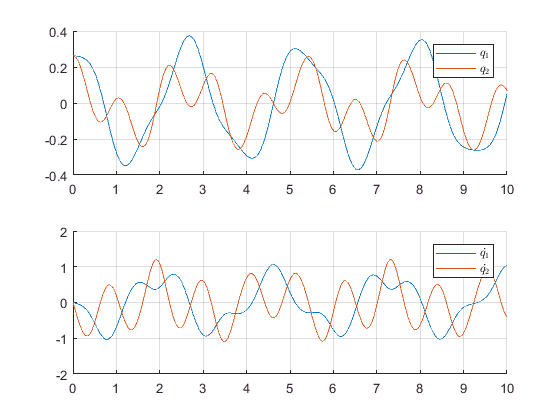

figure
subplot(2,1,1)
grid on
hold on
plot(tsol, ysol(:, 1:2))
h = legend('$q_{1}$', '$q_{2}$');
set(h,'Interpreter','latex')

subplot(2,1,2)
grid on
hold on
plot(tsol, ysol(:, 3:4))
h = legend('$\dot{q_{1}}$', '$\dot{q_{2}}$');
set(h,'Interpreter','latex')

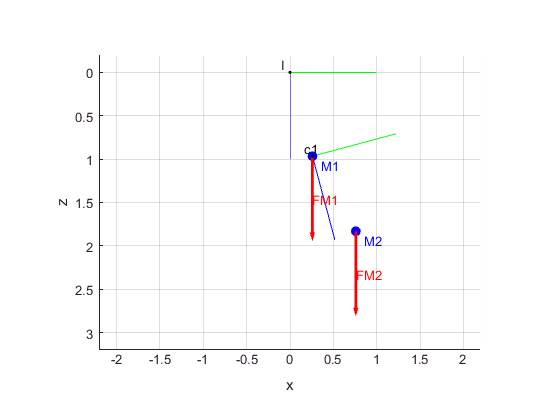

limits = [-2.2 2.2 -2 2 -.2 3.2];
visualize(m, {q1, q2, m1, m2, l}, [ysol(1,1), ysol(1,2), m1v, m2v, lv], 'axis', limits, 'view', [0 0], 'revz', 1);